% LSPB Trajectory Planning
% Given parameters
q0 = 0;      % initial position
qf = 10;     % final position
v_max = 2;   % maximum velocity
a_max = 1;   % maximum acceleration

% Time to reach maximum velocity (v_max) and distance covered during acceleration
t_acc = v_max / a_max;
d_acc = 0.5 * a_max * t_acc^2;

% Determine if LSPB profile is feasible with given constraints
if 2*d_acc > (qf - q0)
    error('The given parameters are not feasible for an LSPB trajectory.');
end

% Calculate the blending time and distances
d_cnst = (qf - q0) - 2 * d_acc; % distance with constant velocity
t_cnst = d_cnst / v_max;        % time with constant velocity
t_total = 2 * t_acc + t_cnst;   % total time of the trajectory

% Time vector
t = linspace(0, t_total, 1000);

% Preallocate arrays for position, velocity, and acceleration
q = zeros(size(t));
v = zeros(size(t));
a = zeros(size(t));

Cách 1

% Compute the trajectory
for i = 1:length(t)
    if t(i) < t_acc
        % Acceleration phase
        a(i) = a_max;
        v(i) = a_max * t(i);
        q(i) = q0 + 0.5 * a_max * t(i)^2;
    elseif t(i) < (t_acc + t_cnst)
        % Constant velocity phase
        a(i) = 0;
        v(i) = v_max;
        q(i) = q0 + d_acc + v_max * (t(i) - t_acc);
    else
        % Deceleration phase
        a(i) = -a_max;
        v(i) = v_max - a_max * (t(i) - t_acc - t_cnst);
        q(i) = q0 + d_acc + d_cnst + v_max * (t(i) - t_acc - t_cnst) - 0.5 * a_max * (t(i) - t_acc - t_cnst)^2;
    end
end

Cách 2

% Compute the trajectory using numerical integration
dt = t(2) - t(1); % Time step size

for i = 2:length(t)
    if t(i) < t_acc
        % Acceleration phase
        a(i) = a_max;
    elseif t(i) < (t_acc + t_cnst)
        % Constant velocity phase
        a(i) = 0;
    else
        % Deceleration phase
        a(i) = -a_max;
    end
    % Update velocity and position using numerical integration
    v(i) = v(i-1) + a(i) * dt;
    q(i) = q(i-1) + v(i) * dt;
end

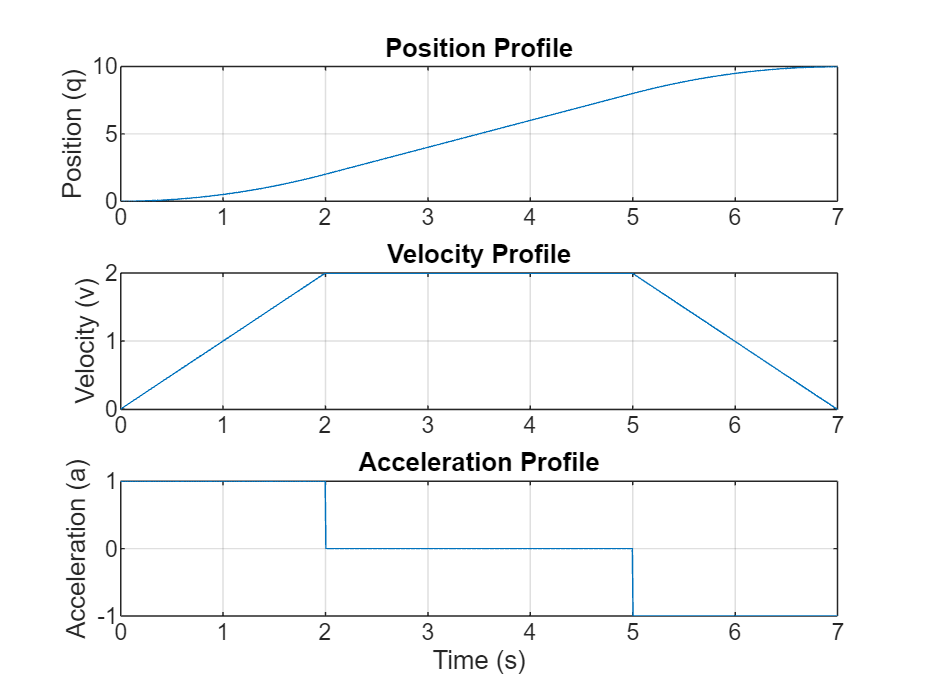

% Plot the trajectory
figure;
subplot(3,1,1);
plot(t, q);
title('Position Profile');
ylabel('Position (q)');
grid on;

subplot(3,1,2);
plot(t, v);
title('Velocity Profile');
ylabel('Velocity (v)');
grid on;

subplot(3,1,3);
plot(t, a);
title('Acceleration Profile');
ylabel('Acceleration (a)');
xlabel('Time (s)');
grid on;